# Step 5: 時間シミュレーションの条件

時間シミュレーションの条件は、シナリオ（`Scenario`）にまとめます。シナリオは、シミュレーションの時間と、事故などの外乱（イベント）を持ちます。この Step では、シナリオの作り方、5 種類のイベントの加え方、イベントの書き換えと削除、シナリオのコピーと保存を説明します。結果の読み方は Step 6 で説明します。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

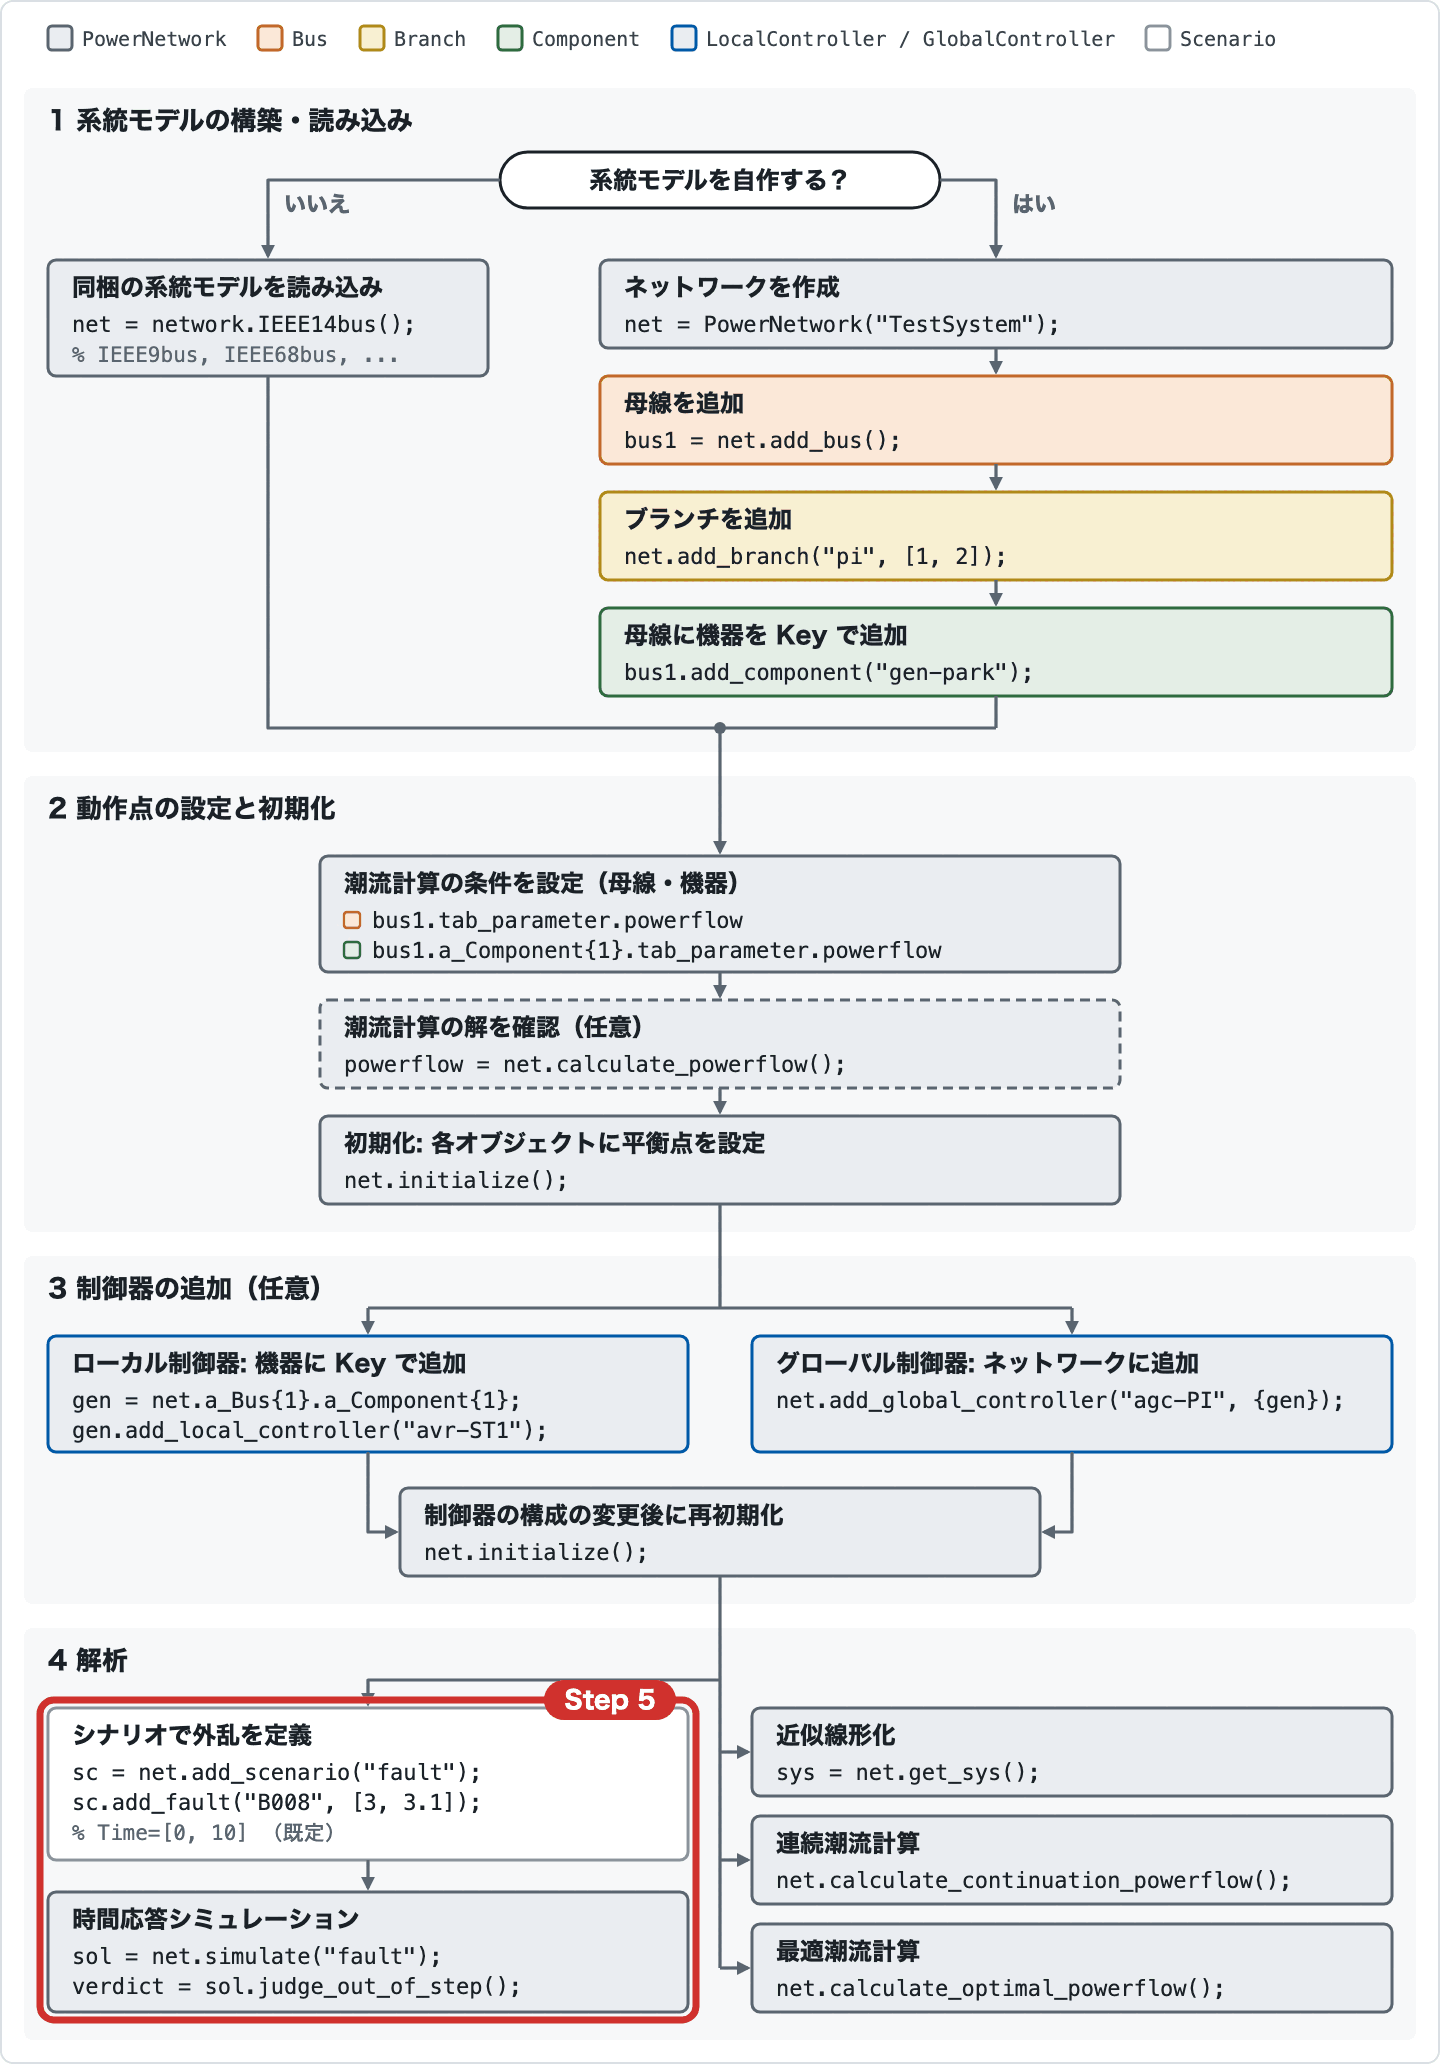

## この Step で分かること

- `net.add_scenario` でシナリオを作り、`net.simulate(tag)` で実行する方法

- 外乱を加えるメソッド: `add_fault`（地絡）、`add_open_branch`（ブランチの開放）、`add_trip`（解列）、`add_offset`（状態のずれ）、`add_input`（入力の追加）

- 外乱が切り替わる時刻で分かれる「フェーズ」

- イベントの書き換え（`edit`）と削除（`remove_event`）、シナリオの時間の変え方

- シナリオのコピー（`From`、`Event`）と、ファイルへの保存（`net.export`）

各節のコードは、その節の作業に要るものだけです。中身を表示して確かめるコードは「**確かめる（省略できます）**」の下に分けてあります。飛ばしても、最後まで実行できます。

時間シミュレーションの考え方は、Part 3 と知識ページ [Part 3: 時間シミュレーション](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part3-time-simulation.html","-browser")) で説明しています。

**注意:** GUILDA を起動してから（`>> GUILDA`）実行してください。

## 1. 系統を読み込んで平衡点を求める

同梱の IEEE 9 母線系統（発電機 3 台。それぞれに AVR と PSS 付き）を読み込み、`initialize` で平衡点を求めます。時間シミュレーションは、この平衡点を初期値にして始まります。

net = network.IEEE9bus(LocalController=true);
[~, flag] = net.initialize();
flag

flag = 1

`flag` が 1 なら、平衡点が求まっています。

**注意:** モデルを書き換えた後は、もう一度 `initialize` してからシミュレーションします。平衡点が古いままだと `simulate` はエラーになります（Step 4）。

## 2. シナリオを作って実行する

`add_scenario` は、タグを付けてシナリオを作り、系統に加えます。`Time` がシミュレーションの時間 [s]（既定 `[0, 10]`）、`Description` が説明です。タグは省略でき、省略すると `"CASE"` になります。

sc = net.add_scenario("noEvent", Time=[0 5], Description="外乱なし");

シナリオは系統の `a_Scenario` に入ります。シミュレーションは、シナリオのタグを指定して実行します。`Progress="none"` は、計算の進み具合の表示を出さない指定です（`simulate` のオプションは Step 6）。

[result, flag] = net.simulate("noEvent", Progress="none");
flag

flag = 1

**確かめる（省略できます）**

作ったシナリオを表示します。外乱のないシナリオでは、平衡点から動かないはずです。`get_trajectory`（Step 6）で 3 台の発電機の回転の速さのずれを取り出すと、計算誤差の大きさにとどまっています。

sc

sc =   Scenario のプロパティ:

    a_PowerNetwork: [1×1 network.IEEE9bus]
           a_Event: {0×1 cell}
         tab_event: [0×5 table]
         tab_input: [0×6 table]
        tab_offset: [0×5 table]
              Time: [0 5]
       Description: "外乱なし"
     tab_parameter: [0×0 table]
             s_tag: "noEvent"


tab_omega = result.get_trajectory("omega");
max(abs(tab_omega{:, 2:end}), [], "all")

ans = 3.7591e-17

**注意:** タグが系統の中で使われている（母線、ブランチ、グローバル制御器、ほかのシナリオ）ときは、末尾に番号が付きます。実際のタグは `sc.s_tag` で確かめます。

## 3. 母線の地絡（add_fault）

`add_fault(母線のタグ, [開始, 終了])` で、母線の地絡を加えます。地絡の間、その母線の電圧は 0 になります。母線 7 を 1 秒から 0.1 秒間、地絡させ、実行して母線の電圧の大きさを描きます。

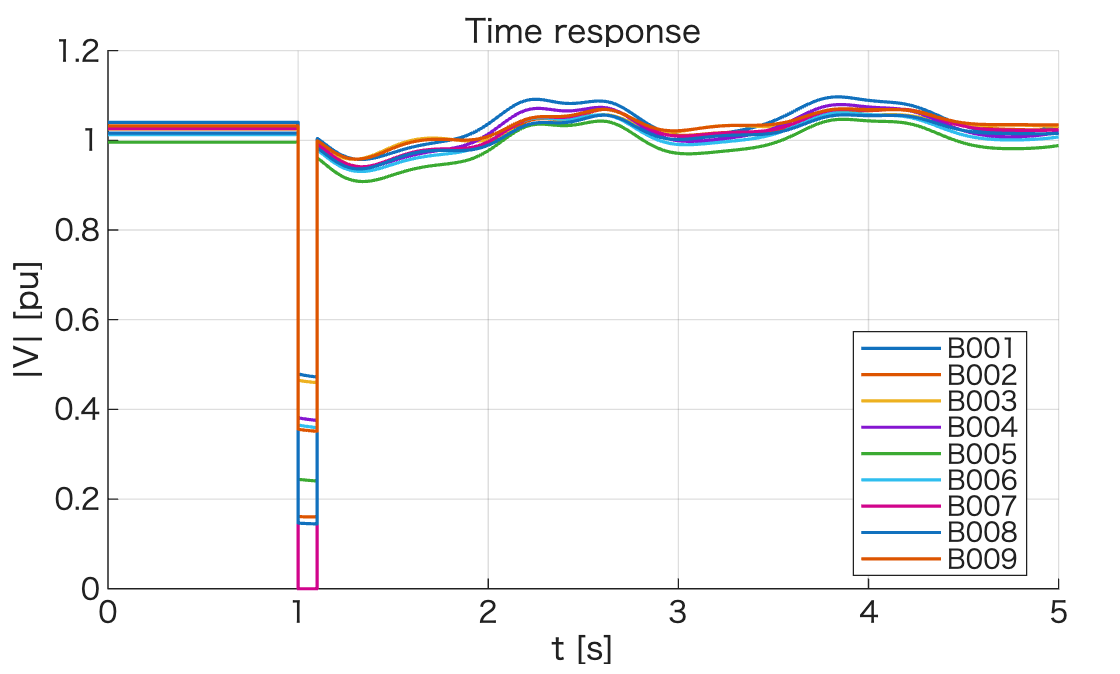

scFault = net.add_scenario("busFault", Time=[0 5]);
evFault = scFault.add_fault("B007", [1, 1.1]);
resFault = net.simulate("busFault", Progress="none");
resFault.plot_trajectory(Quantity="Vabs");

`add_fault` は、作ったイベント（`EventFault`）を返します。複数の母線を同時に地絡させるときは、`add_fault(["B005","B007"], [1, 1.1])` のようにタグを並べます。

**確かめる（省略できます）**

イベントの `s_tag` がイベントのタグ（`Fault001`）で、シナリオが付けます。シナリオの地絡と解列・開放の一覧は `tab_event` です。1 つのイベントが 2 行になり、1 秒に地絡（`BG`）が始まり、1.1 秒に地絡がなくなる（`none`）、という意味です。

evFault

evFault =   EventFault のプロパティ:

     sv_target: "B007"
       rr_time: [1 1.1000]
      s_status: "BG"
       r_point: NaN
         s_tag: "Fault001"
    a_Scenario: [1×1 Scenario]


scFault.tab_event

ans = 2×5 table
       Tag        Target    Time    Status    Point
    __________    ______    ____    ______    _____

    "Fault001"    "B007"      1     "BG"       NaN 
    "Fault001"    "B007"    1.1     "none"     NaN 


## 4. ブランチの地絡と開放（add_fault、add_open_branch）

ブランチ（送電線）の途中の地絡は、`Status` と `Point` を指定します。`Point` は From 側の端（0）から To 側の端（1）までの位置、`Status` は `"3LG"`（1 回線）か `"6LG"`（すべての回線）です。IEEE 9 母線系統のブランチは 2 回線です。

送電線 `EL006`（母線 5〜7）の 1 回線を From 側から 30 % の位置で地絡させ、0.1 秒後にその回線を開きます。開放は `add_open_branch` で、`Status` は `"3open"`（1 回線）か `"6open"`（すべての回線、既定）です。開放は時刻を 1 つだけ受け取り、その時刻から最後まで開いたままです。

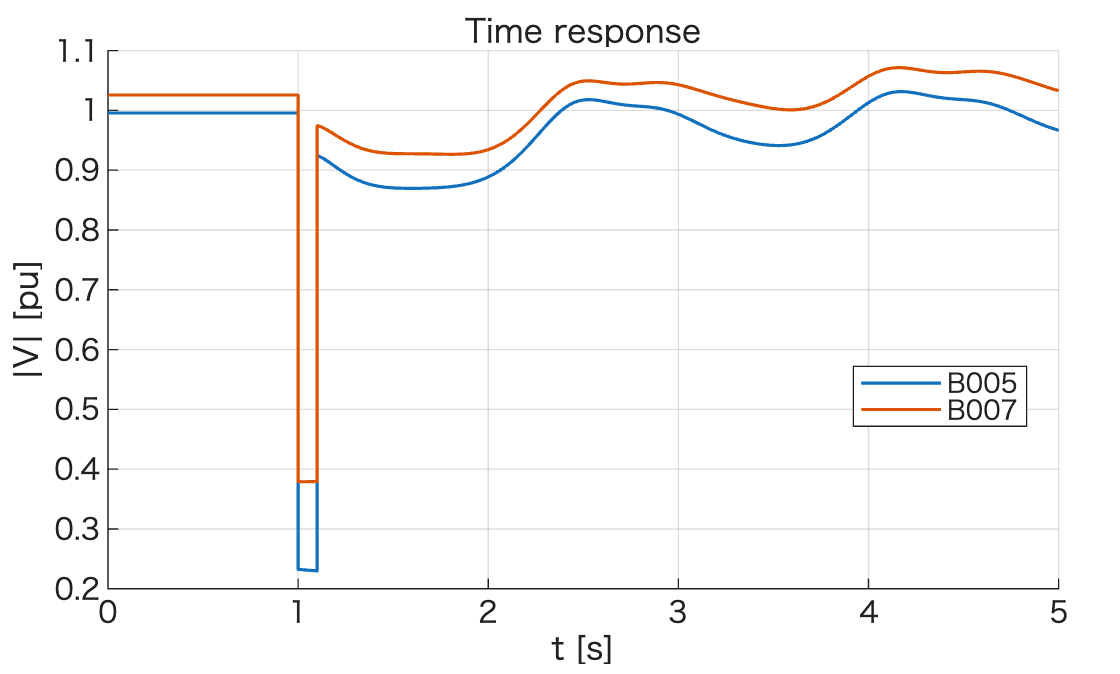

scLine = net.add_scenario("lineFault", Time=[0 5]);
scLine.add_fault("EL006", [1, 1.1], Status="3LG", Point=0.3);
scLine.add_open_branch("EL006", 1.1, Status="3open");
resLine = net.simulate("lineFault", Progress="none");
resLine.plot_trajectory(Quantity="Vabs", Bus=["B005", "B007"]);

地絡の間に母線 5 と母線 7 の電圧が下がり、開放の後は、発電機の揺れに合わせて揺れながら元の値の近くに戻っていきます。地絡と開放の [その他のオプションはこちら（add_fault）](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=Scenario&method=add_fault')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))・[（add_open_branch）](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=Scenario&method=add_open_branch')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

**確かめる（省略できます）**

ブランチのタグと両端の母線は `get_element_table`、回線の数は `get_parameter` の `circuit` の列で確かめられます。開放のイベントのタグは `Parallel001` です（解列と開放は `Parallel<番号>` のタグになります）。

net.get_element_table(Kind="branch")

ans = 9×12 table
               Tag        Kind            Key                    Class             Role    Bus    Parent     From       To      State    Input    Output
             _______    ________    ________________    _______________________    ____    ___    ______    ______    ______    _____    _____    ______

    ET001    "ET001"    "branch"    "pi_transformer"    "branch.pi_transformer"     ""     ""       ""      "B001"    "B004"     ""       ""        ""  
    ET002    "ET002"    "branch"    "pi_transformer"    "branch.pi_transformer"     ""     ""       ""      "B002"    "B007"     ""       ""        ""  
    ET003    "ET003"    "branch"    "pi_transformer"    "branch.pi_transformer"     ""     ""       ""      "B003"    "B009"     ""       ""        ""  
    EL004    "EL004"    "branch"    "pi"                "branch.pi"                 ""     ""       ""      "B004"    "B005"     ""       ""        ""  
    EL005    "EL005"    "branch"    "pi"                "branch.

net.get_parameter("dynamics", Class="Branch")

ans = 9×6 table
               R         X         C       tap    phase    circuit
             ______    ______    ______    ___    _____    _______

    ET001         0    0.0576         0      1       0        2   
    ET002         0    0.0625         0      1       0        2   
    ET003         0    0.0586         0      1       0        2   
    EL004      0.01     0.085     0.088    NaN     NaN        2   
    EL005     0.017     0.092     0.079    NaN     NaN        2   
    EL006     0.032     0.161     0.153    NaN     NaN        2   
    EL007     0.039      0.17     0.179    NaN     NaN        2   
    EL008    0.0085     0.072    0.0745    NaN     NaN        2   
    EL009    0.0119    0.1008    0.1045    NaN     NaN        2   


scLine.tab_event

ans = 3×5 table
         Tag         Target     Time    Status     Point
    _____________    _______    ____    _______    _____

    "Fault001"       "EL006"      1     "3LG"       0.3 
    "Fault001"       "EL006"    1.1     "none"      0.3 
    "Parallel001"    "EL006"    1.1     "3open"     NaN 


**注意**

- 送電線の端での地絡は、母線の地絡（`add_fault(母線, ...)`）として加えます。

- ブランチを開いて、機器のない部分が系統から切り離されるときはエラーになります。

## 5. 解列（add_trip）

`add_trip(タグ, 時刻)` は、機器や制御器を、その時刻から最後まで系統から切り離します。母線 8 の負荷（`B008LRX1`）を 1 秒から最後まで切り離すシナリオを作り、発電機の回転の速さを描きます。

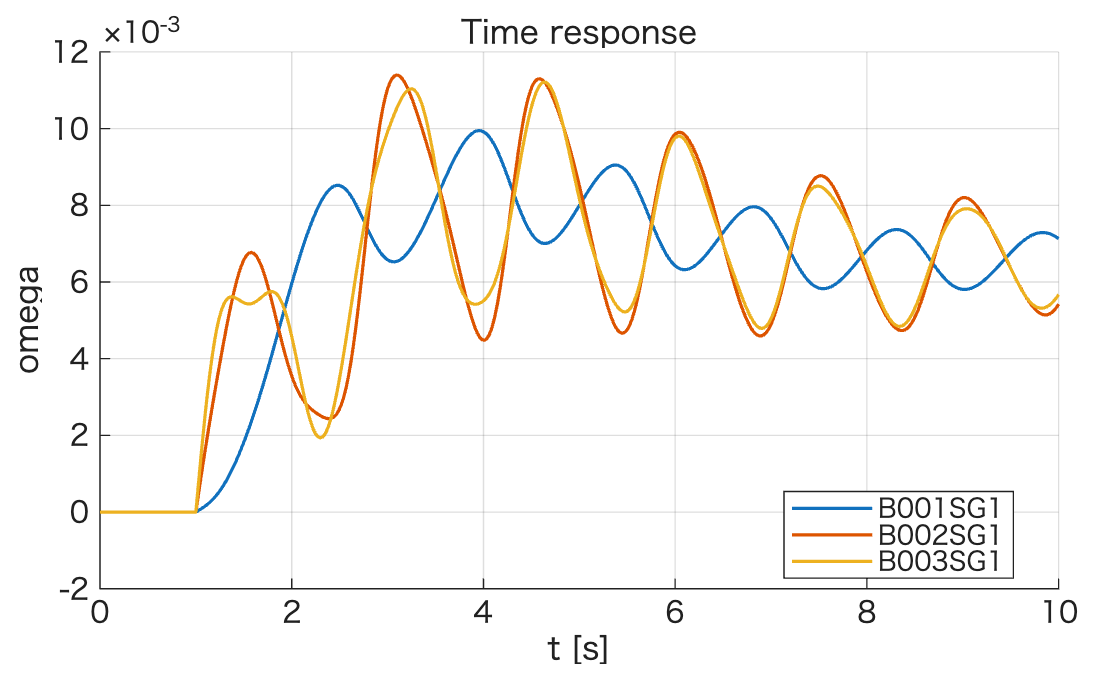

scTrip = net.add_scenario("loadTrip", Time=[0 10]);
scTrip.add_trip("B008LRX1", 1);
resTrip = net.simulate("loadTrip", Progress="none");
resTrip.plot_trajectory(Quantity="omega");

負荷がなくなると発電が余るので、3 台の発電機は揺れながら、そろって速くなります。

制御器も同じように切り離せます。発電機 2 の PSS（`B002SG1CP2`）を 1 秒に切り離すイベントを加えます（12 節で保存します）。

scTrip.add_trip("B002SG1CP2", 1);

**確かめる（省略できます）**

機器と制御器のタグは `get_element_table` で確かめられます。`Owner` に母線や機器のタグを指定すると、その下にあるものだけを並べます。加えた 2 つの解列は `tab_event` に並びます。

net.get_element_table(Owner="B008")

ans = 1×12 table
                   Tag           Kind              Key                     Class               Role     Bus      Parent    From    To    State    Input     Output
                __________    ___________    ________________    __________________________    ____    ______    ______    ____    __    _____    ______    ______

    B008LRX1    "B008LRX1"    "component"    "load-impedance"    "component.load.impedance"     ""     "B008"    "B008"     ""     ""     ""      "R, X"      ""  


net.get_element_table(Owner="B002SG1")

ans = 3×12 table
                      Tag          Kind          Key                    Class                   Role        Bus         Parent       From    To         State                 Input             Output 
                  ____________    _______    ____________    ____________________________    __________    ______    ____________    ____    __    ________________    ____________________    ________

    B002SG1CA1    "B002SG1CA1"    "local"    "avr-ST1"       "controller.avr.AVR_ST1"        "avr"         "B002"    "B002SG1"        ""     ""    "Vtr, Vap, Vst"     "Vref, Vpss, Ifield"    "Vfield"
    B002SG1CP2    "B002SG1CP2"    "local"    "pss-PSS1"      "controller.pss.PSS1"           "pss"         "B002"    "B002SG1CA1"     ""     ""    "xiWS, xi1, xi2"    "omega"                 "Vpss"  
    B002SG1CG1    "B002SG1CG1"    "local"    "gov-static"    "controller.governor.Static"    "governor"    "B002"    "B002SG1"        ""     ""    ""                  "Pmech_ref"    

scTrip.tab_event

ans = 2×5 table
         Tag            Target       Time    Status    Point
    _____________    ____________    ____    ______    _____

    "Parallel001"    "B008LRX1"       1      "open"     NaN 
    "Parallel002"    "B002SG1CP2"     1      "open"     NaN 


**注意**

- 解列した後、その機器や制御器の状態は、結果の中で最後まで `NaN` になります。解列と開放には、元に戻す（再接続する）指定はありません。

- 切り離した制御器の出力は、平衡点の値のままになります。たとえば AVR を切り離すと、界磁電圧は平衡点の値のままです。界磁を失うような外乱は、入力（7 節）で表します。

- グローバル制御器（Step 2）も、タグを指定して切り離せます。

## 6. 初期値を変える（add_offset）

シミュレーションは平衡点から始まります。`add_offset(機器のタグ, 状態の名前, ずれ, 時刻)` は、指定した時刻に状態をずらします。時刻を 0 にすると、初期値を平衡点からずらしたことになります。

発電機 2 の回転子の角度 `delta` を 0.3 rad、回転の速さ `omega` を 0.005 pu ずらします。値は状態ごとに 1 つずつ並べます。`Tag` でイベントに名前を付けられます。

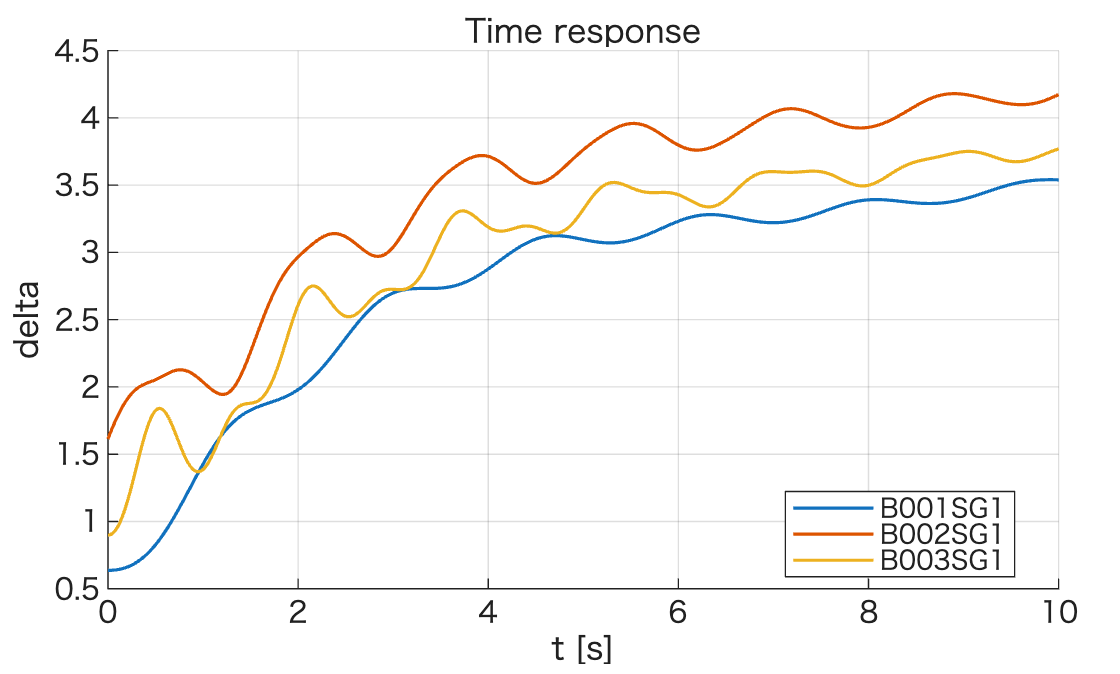

scOffset = net.add_scenario("offset", Time=[0 10]);
scOffset.add_offset("B002SG1", ["delta"; "omega"], [0.3; 0.005], 0, Tag="kick");
resOffset = net.simulate("offset", Progress="none");
resOffset.plot_trajectory(Quantity="delta");

発電機 2 が揺れ、揺れは時間とともに小さくなります。

**確かめる（省略できます）**

状態の名前は `get_element_table` の `State` の列（機器の `sv_x`）で確かめます。状態のずれは `tab_event` ではなく `tab_offset` に入ります。

tab_component = net.get_element_table(Kind="component");
tab_component(:, ["Key", "State", "Input"])

ans = 6×3 table
                      Key                 State                Input     
                ________________    __________________    _______________

    B001SG1     "gen-1axis"         "delta, omega, Eq"    "Pmech, Vfield"
    B002SG1     "gen-1axis"         "delta, omega, Eq"    "Pmech, Vfield"
    B003SG1     "gen-1axis"         "delta, omega, Eq"    "Pmech, Vfield"
    B005LRX1    "load-impedance"    ""                    "R, X"         
    B006LRX1    "load-impedance"    ""                    "R, X"         
    B008LRX1    "load-impedance"    ""                    "R, X"         


scOffset.tab_offset

ans = 1×5 table
     Tag      TimeSpan    OffsetUnit    OffsetState     OffsetValue 
    ______    ________    __________    ____________    ____________

    "kick"       0        "B002SG1"     {2×1 string}    {2×1 double}


**注意**

- 時刻を 0 より後にすると、その時刻に状態を突然ずらす外乱になります。

- 状態のずれと入力（7 節）のタグは、指定しなければ `offset1`、`input1`、... になります。`Fault` や `Parallel` に数字を続けたタグは使えません。

- 平衡点そのものを変えるには、モデルを書き換えて `initialize` し直します（Step 3、Step 4）。

## 7. 入力を加える（add_input）

`add_input(機器のタグ, 入力の名前, 値, [開始, 終了])` は、機器の入力に値を足します。同期発電機の入力は機械入力 `Pmech` と界磁電圧 `Vfield` です。

値が 1 つの数なら、開始から終了まで一定の値を足します。発電機 3 の機械入力を、1 秒から 6 秒まで 0.1 pu 下げます。

scInput = net.add_scenario("input", Time=[0 10]);
scInput.add_input("B003SG1", "Pmech", -0.1, [1, 6]);

値を時系列 `[時刻, 値]` で渡すと、時間とともに変わる入力になります。時刻は開始からの時間です。発電機 2 の機械入力を、2 秒から 1 秒かけて 0.05 pu まで増やし、そのまま保ちます。`Method` は時系列の補間の方法で、`"foh"`（直線、既定）、`"zoh"`（前の値を保つ）、`"spline"` があります。時系列の最後の時刻の後は、最後の値を保ちます。

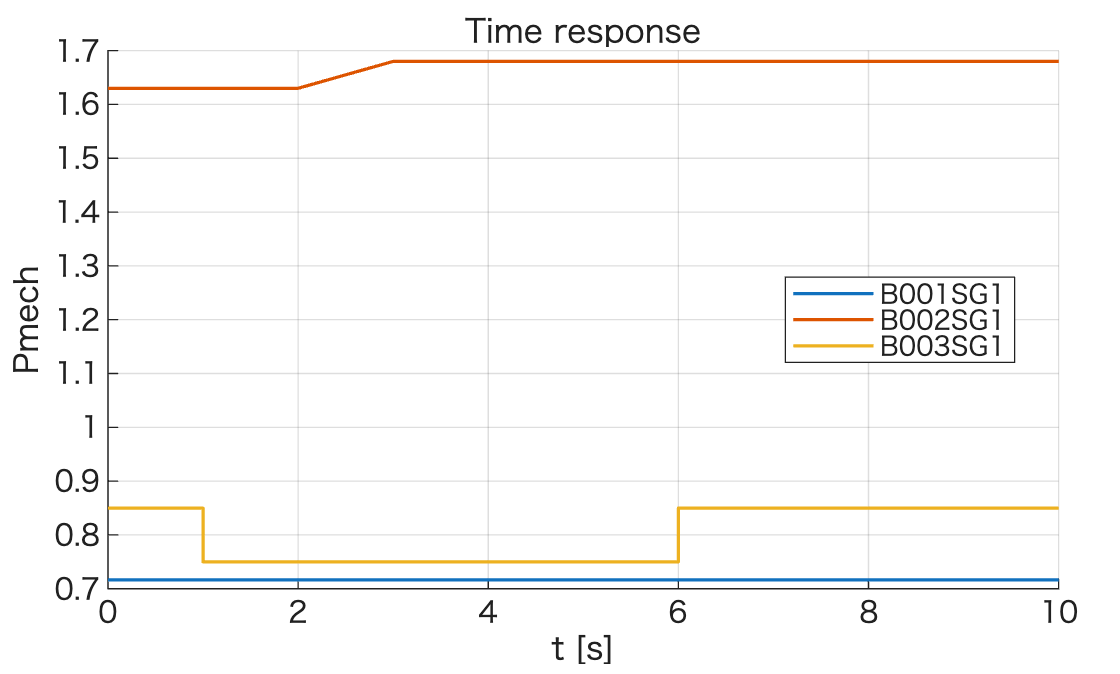

scInput.add_input("B002SG1", "Pmech", [0, 0; 1, 0.05], [2, 10], Method="foh");
resInput = net.simulate("input", Progress="none");
resInput.plot_trajectory(Quantity="Pmech");

描いた `Pmech` は、平衡点の値に `add_input` で足した値を加えたものです。発電機 3 は 1〜6 秒の間だけ下がり、発電機 2 は 2〜3 秒で増えて、その後は一定です。時系列を table で渡す方法など、[その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=Scenario&method=add_input')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

**確かめる（省略できます）**

入力の名前は、機器の `sv_u`（6 節の表の `Input` の列）で確かめます。加えた入力の一覧は `tab_input` です。

net.get_element("B003SG1").sv_u'

ans = 1×2 の string 配列
    "Pmech"    "Vfield"


scInput.tab_input

ans = 2×6 table
      Tag       TimeSpan    InputUnit     InputName      InputValue     InputMethod
    ________    ________    _________    ___________    ____________    ___________

    "input1"    1     6     "B003SG1"    {["Pmech"]}    {[ -0.1000]}       ""      
    "input2"    2    10     "B002SG1"    {["Pmech"]}    {2×2 double}       "foh"   


**注意**

- 同じ機器への入力や状態のずれが重なると、足し合わされます。

- 負荷の入力（定インピーダンス負荷では `R`、`X`）を変えると、負荷の変化を表せます。

## 8. 複数の外乱を組み合わせる

1 つのシナリオに、何種類のイベントでも加えられます。母線 8 の地絡を 0.1 秒で除去し、同時に送電線 `EL009`（母線 8〜9）を開き、3 秒に母線 6 の負荷を切り離すシナリオを作ります。後で書き換えるので、イベントを変数に受け取ります。

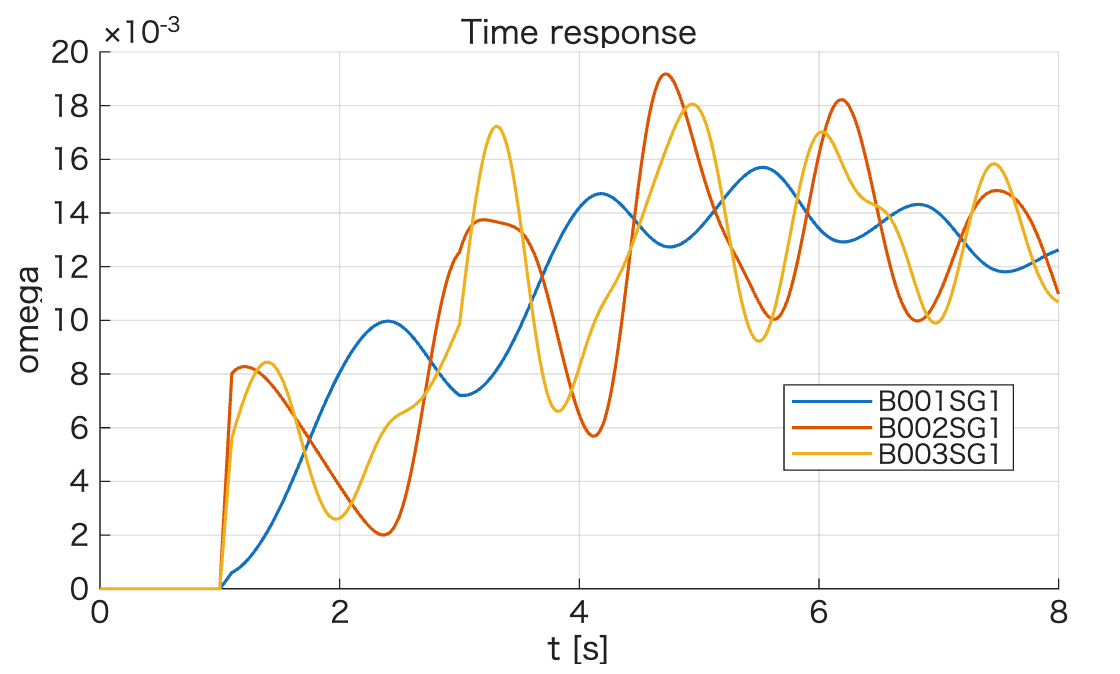

scMulti = net.add_scenario("multi", Time=[0 8], Description="B008 地絡 → EL009 開放 → B006 負荷の解列");
evMultiFault = scMulti.add_fault("B008", [1, 1.1]);
evMultiOpen  = scMulti.add_open_branch("EL009", 1.1);
evMultiTrip  = scMulti.add_trip("B006LRX1", 3);
resMulti = net.simulate("multi", Progress="none");
resMulti.plot_trajectory(Quantity="omega");

シミュレーションは、外乱の組み合わせが変わる時刻ごとに区切られた「フェーズ」ごとに計算されます。1〜1.1 秒が地絡、1.1 秒からは送電線が 1 本少ない系統、3 秒からは負荷も 1 つ少ない系統で計算しています。

**確かめる（省略できます）**

`a_Event` には、加えた順にイベントが入ります。フェーズの一覧は、結果の `output.phases` にあります（`simulate` に `Verbose=true` を付けると、実行の前にも表示します）。

scMulti.a_Event

ans = 3×1 の cell 配列
    {1×1 EventFault     }
    {1×1 EventOpenBranch}
    {1×1 EventTrip      }


scMulti.tab_event

ans = 4×5 table
         Tag           Target      Time    Status     Point
    _____________    __________    ____    _______    _____

    "Fault001"       "B008"          1     "BG"        NaN 
    "Fault001"       "B008"        1.1     "none"      NaN 
    "Parallel001"    "EL009"       1.1     "6open"     NaN 
    "Parallel002"    "B006LRX1"      3     "open"      NaN 


resMulti.output.phases

ans = 4×6 table
    t1     t2     Fault001    Parallel001    Parallel002    NoAction1
    ___    ___    ________    ___________    ___________    _________

      0      1     false         false          false         true   
      1    1.1     true          false          false         false  
    1.1      3     false         true           false         false  
      3      8     false         true           true          false  


**注意:** 同じ母線の地絡どうしが重なるとエラーになります。終わりと始まりがちょうど接する（`[1 2]` と `[2 3]`）のはかまいません。解列と開放は、同じ対象に 1 つまでです。

## 9. イベントを書き換える・外す（edit、remove_event）

イベントの値（`rr_time` など）は直接は書き換えられません。`edit` に、`add_*` と同じ名前のオプションを渡して書き換えます。渡さなかったものは元の値のままです。地絡の除去を 0.15 秒後に遅らせ、送電線の開放の時刻もそろえます。

evMultiFault.edit(Time=[1, 1.15]);
evMultiOpen.edit(Time=1.15);

イベントを外すには、`remove_event` にイベントのタグを渡します。説明（`Description`）は、プロパティに代入して書き換えます。

scMulti.remove_event(evMultiTrip.s_tag);
scMulti.Description = "B008 地絡 → EL009 開放";

`edit` に渡せるオプションは、イベントの種類ごとに違います。地絡のイベントの [その他のオプションはこちら（EventFault の edit）](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=EventFault&method=edit')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。ほかの種類は、それぞれのクラス（`EventTrip`、`EventOpenBranch`、`EventOffset`、`EventInput`）の `edit` のページにあります。

**確かめる（省略できます）**

書き換えた結果の一覧です。地絡の終わりと開放が 1.15 秒になり、負荷の解列がなくなっています。

scMulti.tab_event

ans = 3×5 table
         Tag         Target     Time    Status     Point
    _____________    _______    ____    _______    _____

    "Fault001"       "B008"        1    "BG"        NaN 
    "Fault001"       "B008"     1.15    "none"      NaN 
    "Parallel001"    "EL009"    1.15    "6open"     NaN 


書き換えや追加の結果、外乱が重なるなどの誤りがあると、エラーになり、シナリオは元のままです。ここでは、母線 8 の地絡と重なる地絡を加えようとしてみます。

try
    scMulti.add_fault("B008", [1.1, 1.2]);
catch ME
    disp(ME.message)
end

Events "Fault001" and "Fault002" of scenario "multi" overlap on B008 ([1 1.15] and [1.1 1.2]). Two faults of one target may touch but not overlap, and a target has at most one parallel event (trip, branch opening), which lasts to the end of the simulation. Change the times, or remove one with remove_event.


**注意:** 外したイベントは、もうシナリオに属しません。同じ外乱は `add_*` で加え直します。

## 10. シミュレーションの時間を変える

シナリオの時間は `Time` プロパティで変えられます。`simulate` の `Time` オプションを指定すると、その呼び出しだけ時間を置き換えます。

scMulti.Time = [0 6];
resShort = net.simulate("multi", Progress="none", Time=[0 2]);

**確かめる（省略できます）**

結果は 0〜2 秒で、シナリオの `Time` は `[0 6]` のままです。

[resShort.rv_t(1), resShort.rv_t(end)]

ans =      0     2


scMulti.Time

ans =      0     6


**注意:** 地絡や入力の終わりの時刻がシミュレーションの終わりより後でも（`Inf` でも）かまいません。その外乱は最後まで続きます。外乱の時刻によってシミュレーションの時間が変わることはありません。

## 11. シナリオをコピーする・作り直す

### 11.1 ほかのシナリオからコピーする

`From` を指定すると、ほかのシナリオのイベント、時間、説明をコピーしたシナリオを作れます。コピー元のシナリオは変わりません。別の系統のシナリオもコピーできます。

scCopy = net.add_scenario("multiCopy", From=scMulti);

### 11.2 イベントから作る

イベントは、系統なしでコンストラクタ（`EventFault`、`EventTrip`、`EventOpenBranch`、`EventOffset`、`EventInput`）でも作れます。引数は `add_*` と同じです。`Event` に並べて渡すと、それらを持つシナリオができます。

c_event = {EventFault("B005", [1, 1.05]), EventOffset("B001SG1", "delta", 0.1, 0)};
scNew = net.add_scenario("fromEvents", Time=[0 5], Event=c_event);

**確かめる（省略できます）**

コピーしたシナリオと、イベントから作ったシナリオの一覧です。

scCopy.tab_event

ans = 3×5 table
         Tag         Target     Time    Status     Point
    _____________    _______    ____    _______    _____

    "Fault001"       "B008"        1    "BG"        NaN 
    "Fault001"       "B008"     1.15    "none"      NaN 
    "Parallel001"    "EL009"    1.15    "6open"     NaN 


scNew.tab_event

ans = 2×5 table
       Tag        Target    Time    Status    Point
    __________    ______    ____    ______    _____

    "Fault001"    "B005"       1    "BG"       NaN 
    "Fault001"    "B005"    1.05    "none"     NaN 


scNew.tab_offset

ans = 1×5 table
       Tag       TimeSpan    OffsetUnit    OffsetState    OffsetValue
    _________    ________    __________    ___________    ___________

    "offset1"       0        "B001SG1"     {["delta"]}    {[0.1000]} 


### 11.3 シナリオを削除する

要らなくなったシナリオは `remove_scenario` で削除します。

net.remove_scenario(["multiCopy", "fromEvents"]);

**確かめる（省略できます）**

系統にあるシナリオは、`disp_summary` の一覧の `Scenarios` の行で確かめられます（数と、タグを 6 つまで表示します）。

net.disp_summary(bus=false, branch=false, component=false);

PowerNetwork (network.IEEE9bus): 60 Hz, base 100 MVA
- Buses: 9 (slack 1, PV 2, PQ 6); slack bus: B001
- Branches: 9
    - pi_transformer: 3 (ET001, ET002, ET003)
    - pi: 6 (EL004, EL005, EL006, EL007, EL008, EL009)
- Components: 6
    - gen-1axis: 3 (B001SG1, B002SG1, B003SG1)
    - load-impedance: 3 (B005LRX1, B006LRX1, B008LRX1)
- Local controllers: 9 (avr 3, pss 3, governor 3)
    - avr-ST1: 3 (B001SG1CA1, B002SG1CA1, B003SG1CA1)
    - pss-PSS1: 3 (B001SG1CP2, B002SG1CP2, B003SG1CP2)
    - gov-static: 3 (B001SG1CG1, B002SG1CG1, B003SG1CG1)
- Global controllers: none
- Scenarios: 7 (noEvent, busFault, lineFault, loadTrip, offset, input, ... (1 more))
- Equilibrium: up to date


**注意:** 削除したシナリオを入れていた変数（`scCopy`、`scNew`）は、使えなくなります。`add_scenario` の [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=add_scenario')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

## 12. シナリオを保存する

シナリオは、系統と一緒に `net.export` でフォルダに保存します。シナリオは 1 つずつ `scenario/<タグ>.json` に書き出されます。機器と制御器（AVR、PSS、ガバナ）も保存されるので、制御器を対象にしたイベント（5 節の PSS の解列など）を持つシナリオも、そのまま保存できます。

s_folder = fullfile(tempdir, "GUILDA_Step5_IEEE9bus");
net.export(s_folder, Overwrite=true);

保存したフォルダは `PowerNetwork.import` で読み込みます。制御器とシナリオも同じタグで戻り、平衡点も計算し直されます。シナリオも `get_element` でタグから取り出せます。

netLoaded = PowerNetwork.import(s_folder);
scLoaded = netLoaded.get_element("loadTrip");

**確かめる（省略できます）**

書き出したファイルと、5 節のシナリオ `loadTrip` の中身（時間、説明、イベントを書いた JSON）を表示します。読み込んだ系統の一覧と、取り出したシナリオのイベントも表示します。

dir(fullfile(s_folder, "scenario"))


.               ..              busFault.json   input.json      lineFault.json  loadTrip.json   multi.json      noEvent.json    offset.json     



type(fullfile(s_folder, "scenario", "loadTrip.json"))


{
  "Format": "GUILDAscenario",
  "version": 2,
  "Description": "",
  "Time": [
    0,
    10
  ],
  "Event": [
    {
      "Tag": "Parallel001",
      "Target": "B008LRX1",
      "Time": 1,
      "Status": "open",
      "Point": NaN
    },
    {
      "Tag": "Parallel002",
      "Target": "B002SG1CP2",
      "Time": 1,
      "Status": "open",
      "Point": NaN
    }
  ]
}


netLoaded.disp_summary(bus=false, branch=false, component=false);

GUILDA_Step5_IEEE9bus (PowerNetwork): 60 Hz, base 100 MVA
- Buses: 9 (slack 1, PV 2, PQ 6); slack bus: B001
- Branches: 9
    - pi_transformer: 3 (ET001, ET002, ET003)
    - pi: 6 (EL004, EL005, EL006, EL007, EL008, EL009)
- Components: 6
    - gen-1axis: 3 (B001SG1, B002SG1, B003SG1)
    - load-impedance: 3 (B005LRX1, B006LRX1, B008LRX1)
- Local controllers: 9 (avr 3, pss 3, governor 3)
    - avr-ST1: 3 (B001SG1CA1, B002SG1CA1, B003SG1CA1)
    - pss-PSS1: 3 (B001SG1CP2, B002SG1CP2, B003SG1CP2)
    - gov-static: 3 (B001SG1CG1, B002SG1CG1, B003SG1CG1)
- Global controllers: none
- Scenarios: 7 (busFault, input, lineFault, loadTrip, multi, noEvent, ... (1 more))
- Equilibrium: up to date


scLoaded.tab_event

ans = 2×5 table
         Tag            Target       Time    Status    Point
    _____________    ____________    ____    ______    _____

    "Parallel001"    "B008LRX1"       1      "open"     NaN 
    "Parallel002"    "B002SG1CP2"     1      "open"     NaN 


読み込んだ系統で同じシナリオを計算し、元の系統の結果と比べます。負荷と PSS を切り離すこのシナリオは、既定の許容誤差ではソルバーが途中で止まることがあるので、`Tolerance=1e-5` を付けます（Step 6）。

resOrig   = net.simulate("loadTrip", Progress="none", Tolerance=1e-5);
resLoaded = netLoaded.simulate("loadTrip", Progress="none", Tolerance=1e-5);
[resOrig.flag, resLoaded.flag]

ans =      1     1


isequal(resOrig.rv_t, resLoaded.rv_t)

ans = logical
   1


max(abs(resOrig.rm_variable - resLoaded.rm_variable), [], "all")

ans = 0

時刻も値も一致し、保存と読み込みで同じ結果が得られることが分かります（PSS を切り離した後の `NaN` は比べていません）。

**注意**

- 平衡点や、`initialize` で計算する値（LQR のゲインなど）は保存されません。`import` が読み込みの後に `initialize` で計算し直します（`Initialize=false` で省けます）。

- ファイルの形式と系統の読み書きは Step 12 で説明します。

## まとめ

- `net.add_scenario` でシナリオを作り、`net.simulate(tag)` で実行しました。シナリオは時間と外乱（イベント）を持ちます。

- 外乱は `add_fault`（母線・ブランチの地絡）、`add_open_branch`、`add_trip`、`add_offset`、`add_input` で加えます。どれも作ったイベントを返し、一覧は `tab_event`、`tab_offset`、`tab_input` で見られます。

- イベントは `edit` で書き換え、`remove_event` で外します。シナリオは `From`・`Event` でコピーでき、`net.export` で保存できます。

## 次の Step と関係する Part

- 次の Step 6（シミュレーションの結果）では、`simulate` のオプションと、結果（`ResultODE`）からデータを取り出す方法を説明します。

- 臨界除去時間の求め方や、ガバナの効果などの解析の例は Part 3（時間シミュレーション）で扱います（`Part3_TimeSimulation.mlx`）。

[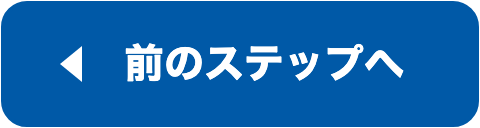](matlab:open('Step4_PowerFlow.mlx'))　　[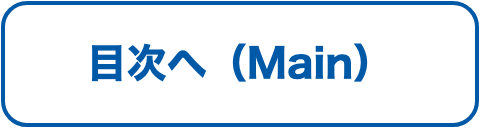](matlab:open('Main.mlx'))　　[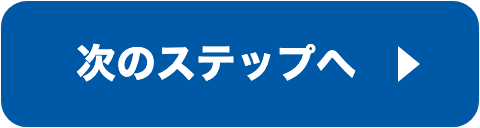](matlab:open('Step6_SimulationResult.mlx'))